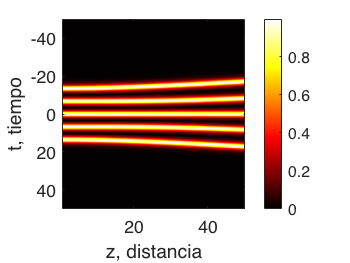

clear all;
clc;

L = 100; %Tiempo
N = 2048;
dx = L/N;
x=[-N/2:1:N/2-1]*dx;
P0 = 1; %Potencia Pico
T0 = 1; %Ancho del Pulso
q0 = 6.75; %Separación entre bits

kappa=(2*pi/L)*[-N/2:1:N/2-1];
kappa=fftshift(kappa);

dz=dx.^2/4; 
zfinal=50; %distancia
pasos=ceil(zfinal/dz);

u_init = sqrt(P0).*sech(T0*(x-(-2)*q0))-sqrt(P0).*sech(T0*(x-(-1)*q0))+sqrt(P0).*sech(T0*(x-(0)*q0))-sqrt(P0).*sech(T0*(x-(1)*q0))+sqrt(P0).*sech(T0*(x-(2)*q0));

utotal=zeros(N,pasos+1);
utotal(:,1) = u_init;
u_n=u_init;
t = 1:dz:zfinal;

for i = 1:1:pasos

    U_NL = fft(exp(j*dz*abs(u_n).^2).*u_n);
    U_D = exp(-j*kappa.^2*dz/2).*U_NL;
    u_n = ifft(U_D);
    utotal(:,i) = u_n;

end

utotal = abs(utotal);

figure(1);
imagesc(t,x,utotal); colorbar;
colormap(hot)
xlabel('z, distancia'); ylabel('t, tiempo');